# Radial Basis Function Network

*© *Copyright 2022 The MathWorks, Inc

## `radbas` to compute weighted and shifted Gaussian RBFs

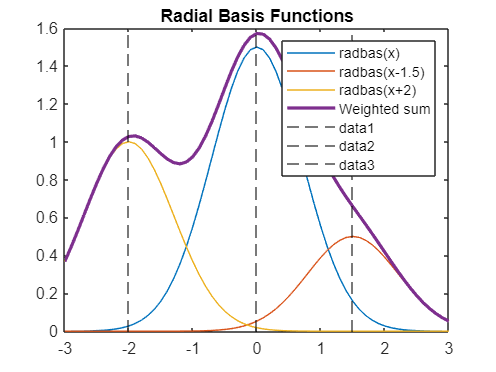

x = -3:.1:3;                             % x = row 1x61 ,
c = [0; 1.5; -2];                        % c = column 3x1
omega = [1.5 0.5 1];                     % omega = row 1x3
a = radbas (x-c);                        % x-c = a matrix 3 x61 ( implicit expansion )

figure
plot(x, omega .*a')                      % plot of 3 wighted RBFs
hold on 
plot(x, omega *a, LineWidth =2) % plot of the sum of the 3 RBF
title('Radial Basis Functions');
legend('radbas(x)','radbas(x-1.5)', 'radbas(x+2)', "Weighted sum")
for i = 1:3, xline(c(i), 'k--'), end

## Training an RBF network to approximate a function


$$f:R^d \longrightarrow R^Q$$


d = 2;                      % input size d
Q = 2;                      % output size Q 
N = 100;                    % N points in R^d, d=2
                                      
in = randn(d,N);                                                                 % in (dxN)
out = sin(in(1,:)).*exp(-0.5*in(1,:)) + sin(in(2,:)).*exp(-0.1*in(2,:));         % out (QxN)
out(2,:)= cos(2*in(1,:)).*exp(-0.1*in(1,:)) + cos(3*in(2,:)).*exp(-0.2*in(2,:)); 

MSEgoal =0.02;
RBFspread = 1;
RBFnet2 = newrb(in, out,MSEgoal,RBFspread);      % train the RBF neural network

NEWRB, neurons = 0, MSE = 1.08437



whos in out RBFnet2

  Name         Size             Bytes  Class      Attributes

  RBFnet2      1x1              29564  network              
  in           2x100             1600  double               
  out          2x100             1600  double               



## Prediction on a grid  and visualization

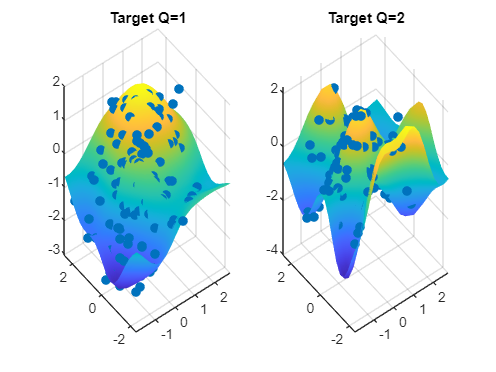

Nx = 20; Ny=20; Q=size(out,1);
xnew = linspace(min(in(1,:)), max(in(1,:)), Nx); 
ynew = linspace(min(in(2,:)), max(in(2,:)), Ny); 
[Xnew,Ynew] = ndgrid(xnew,ynew);                 % Nx x Ny uniform grid
newIn = [Xnew(:),Ynew(:)]';                      % d x M (where M=Nx*Ny)
newOut = RBFnet2(newIn);                         % Q x M
figure
for q = 1:Q                                      
	subplot(1,Q,q)
    scatter3(in(1,:), in(2,:), out(q,:), 'filled'), hold on 
	newOut_q = reshape(newOut(q,:),Nx,Ny);         % reshape 
	surf(Xnew,Ynew,newOut_q)                       % draw surface
    title("Target Q=" + q)
    shading interp
end